4. Empleando las siguientes ecuaciones para el modelo de un péndulo invertido sin par externo,


$$\dot x_1 = x_2\\
\dot x_2 = \frac{g}{l}\sin x_1 - \frac{b}{ml}x_2,$$


a) Linealizar el sistema en torno al punto de equilibrio $\theta =\pi$.

La expansión de Taylor de $\sin \;x$ para $x=\pi \;$es la misma expansión que para $x=0$ pero con signo negativo, de manera que las ecuaciones se convierten en las siguientes:


$$\dot x_1 = x_2\\
\dot x_2 = -\frac{g}{l}x_1 - \frac{b}{ml}x_2.$$


Este sistema linealizado cerca del origen se comportará similar al original cerca del punto de equilibrio.

b) Simular mediante Matlab tanto el sistema original como el linealizado. Emplear para ello $m=g=l=b=1$. Considerar como condiciones iniciales para $X_1$ distintos ángulos cada vez más alejados de $\pi$ y para $x_2 =0$ en todos los casos. Representar en un mismo gráfico la evolución temporal de $x_1$ para el sistema original y el linealizado. Discutir la validez de la aproximación lineal en función del las condiciones iniciales empleadas.

[g, l, b, m] = deal(1);
t_range = [0, 10];
x01 = [pi; 0];
x02 = [pi+pi*0.2; 0];
x03 = [pi+pi*0.5; 0];
x04 = [pi+pi*0.9; 0];

[t1,x1] = ode45(@(t,x)inverted_pendulum(t,x,g,l,b,m), t_range, x01);
[t1lin,x1lin] = ode45(@(t,x)inverted_pendulum_lin(t,x,g,l,b,m), t_range, x01-x01);
[t2,x2] = ode45(@(t,x)inverted_pendulum(t,x,g,l,b,m), t_range, x02);
[t2lin,x2lin] = ode45(@(t,x)inverted_pendulum_lin(t,x,g,l,b,m), t_range, x02-x01);
[t3,x3] = ode45(@(t,x)inverted_pendulum(t,x,g,l,b,m), t_range, x03);
[t3lin,x3lin] = ode45(@(t,x)inverted_pendulum_lin(t,x,g,l,b,m), t_range, x03-x01);
[t4,x4] = ode45(@(t,x)inverted_pendulum(t,x,g,l,b,m), t_range, x04);
[t4lin,x4lin] = ode45(@(t,x)inverted_pendulum_lin(t,x,g,l,b,m), t_range, x04-x01);

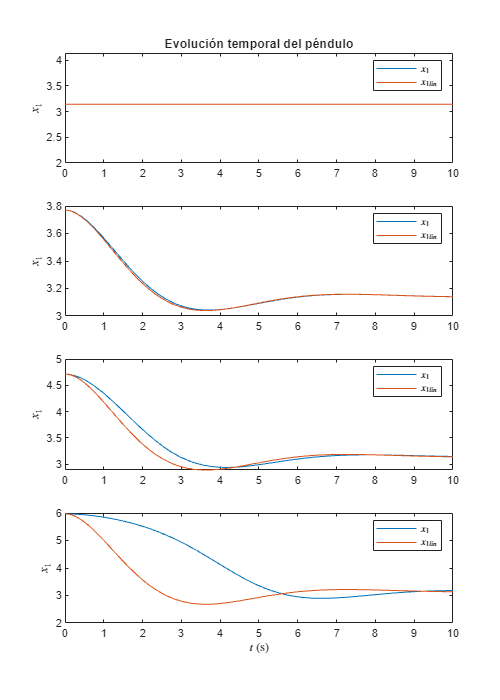

figure(1)
clf
set(gcf, 'Position', [100 100 500 700])
hold off

subplot(4,1,1)
plot(t1,x1(:,1))
hold on
plot(t1lin,x1lin(:,1)+pi)
title('Evolución temporal del péndulo')
ylabel('$x_1$', 'interpreter', 'latex')
legend('$x_1$','$x_{1lin}$','interpreter','latex')

subplot(4,1,2)
plot(t2,x2(:,1))
hold on
plot(t2lin,x2lin(:,1)+pi)
ylabel('$x_1$', 'interpreter', 'latex')
legend('$x_1$','$x_{1lin}$','interpreter','latex')

subplot(4,1,3)
plot(t3,x3(:,1))
hold on
plot(t3lin,x3lin(:,1)+pi)
ylabel('$x_1$', 'interpreter', 'latex')
legend('$x_1$','$x_{1lin}$','interpreter','latex')

subplot(4,1,4)
plot(t4,x4(:,1))
hold on
plot(t4lin,x4lin(:,1)+pi)
ylabel('$x_1$', 'interpreter', 'latex')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$x_1$','$x_{1lin}$','interpreter','latex')

function xdot = inverted_pendulum(t, x, g, l, b, m)
    xdot(1,1) = x(2,1);
    xdot(2,1) = (g/l)*sin(x(1,1)) - (b/m*l)*x(2,1);
end

function xdot = inverted_pendulum_lin(t, x, g, l, b, m)
    xdot(1,1) = x(2,1);
    xdot(2,1) = -(g/l)*x(1,1) - (b/m*l)*x(2,1);
end